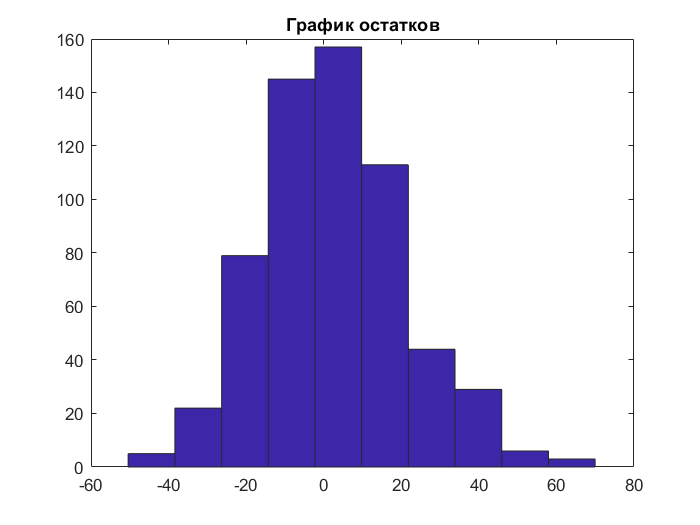


%plot(m_cv(1):m_cv(2),hyp_cv-yr(m_cv(1):m_cv(2)), '-');

title('График остатков')

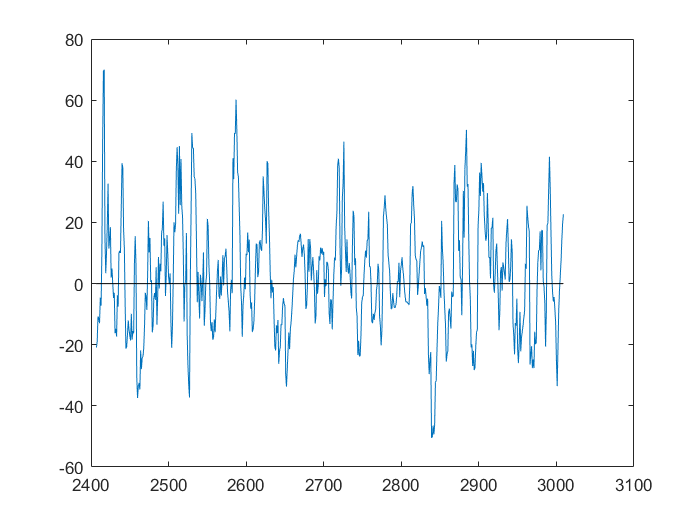

xlabel = 'День';
ylabel = 'Ошибка предсказания';
plot(m_test(1):m_test(2),hyp_test-yr(m_test(1):m_test(2)), '-');
hold on;
plot([m_test(1) m_test(2)],[0 0], 'Color', [0 0 0])
hold off

loss = hyp_test-yr(m_test(1):m_test(2));
fprintf('mean loss = %f', mean(loss));

mean loss = 2.515946

fprintf('std = %f', std(loss));

std = 18.544886

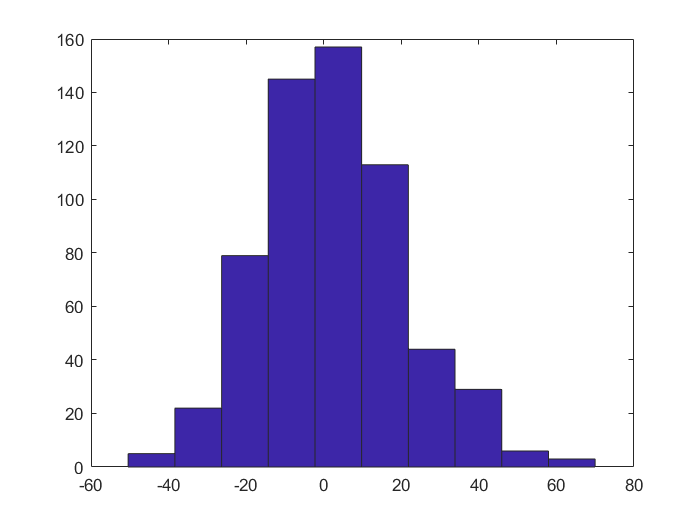

hist(loss)